# Monetary Theory & Banking 

Copyright © 2021, Chloe Wang

% Feb 1, 2021
% Works Cited: Fortin-Gagnon, O., Leroux, M., Stevanovic, D. and S. Surprenant (2018)

## Clear previous programs

clear all; % clears residual programs
close all; % close all previous routines and programs

## Load data

% Read file
CANMD = readtable('CAN_MD.csv')

CANMD = 1283×409 table
    Var1       Date       GDP_new    BSI_new    GPI_new    SPI_new    IP_new    NDM_new    DM_new    OILP_new    CON_new    RT_new    WT_new    PA_new    FIN_new    OIL_CAN_new    EMP_CAN    EMP_SERV_CAN    EMP_FOR_OIL_CAN    EMP_CONS_CAN    EMP_SALES_CAN    EMP_FIN_CAN    EMP_MANU_CAN    EMP_PART_CAN    UNEMP_CAN    UNEMP_DURA_1_4_CAN    UNEMP_DURA_5_13_CAN    UNEMP_DURA_14_25_CAN    UNEMP_DURA_27__CAN    UNEMP_DURAvg_CAN_new    CLAIMS_CAN    <s


% Find the index of Jan 1981
idx = find(CANMD.Date=='1981-01-01') 

idx = 805


% Create a subset starting at January 1981
data = CANMD(805:1283, 2:409)

data = 479×408 table
       Date             GDP_new                 BSI_new                 GPI_new                 SPI_new                  IP_new                 NDM_new                  DM_new                 OILP_new                CON_new                  RT_new                  WT_new                  PA_new           FIN_new    OIL_CAN_new      EMP_CAN      EMP_SERV_CAN    EMP_FOR_OIL_CAN    EMP_CONS_CAN    EMP_SALES_CAN    EMP_FIN_CAN    EMP_MANU_CAN    EMP_PART_CAN    UNEMP_CAN    UNEMP_DURA_1_4_CAN    UNEMP_DURA_5_13_CAN    UNEMP_DUR

## Adding GDP goods and GDP services to create new variable, GDP goods & services

% Convert string to floats
GPI_new = str2double(data.GPI_new);
SPI_new = str2double(data.SPI_new);
GDP_new = str2double(data.GDP_new);
BSI_new = str2double(data.BSI_new);
RT_new = str2double(data.RT_new);

% Create new GDP_GS variable
GDP_GS = (GPI_new + SPI_new);


## Log calculations

% Take log of the 4 variables
lGDP_new = log(GDP_new);
lGDP_GS = log(GDP_GS);
lBSI_new = log(BSI_new);
lRT_new = log(RT_new);

## Using subplots to plot log of each time-series

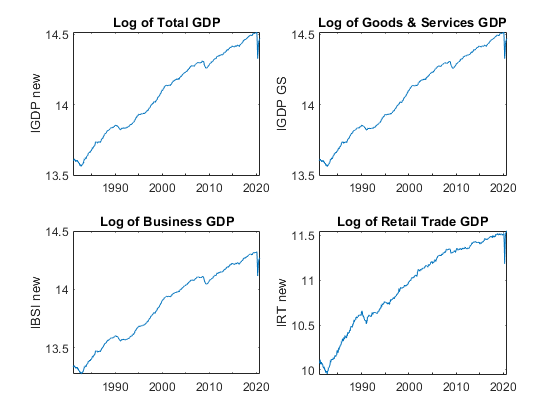

% Plot 
figure(1)
subplot(2,2,1)
plot(data.Date,lGDP_new);
title("Log of Total GDP");
ylabel("lGDP new");

subplot(2,2,2)
plot(data.Date,lGDP_GS);
title("Log of Goods & Services GDP");
ylabel("lGDP GS");

subplot(2,2,3)
plot(data.Date,lBSI_new);
title("Log of Business GDP");
ylabel("lBSI new");

subplot(2,2,4)
plot(data.Date,lRT_new);
title("Log of Retail Trade GDP");
ylabel("lRT new");

Output of commands gives us the following 4x4 graphs:

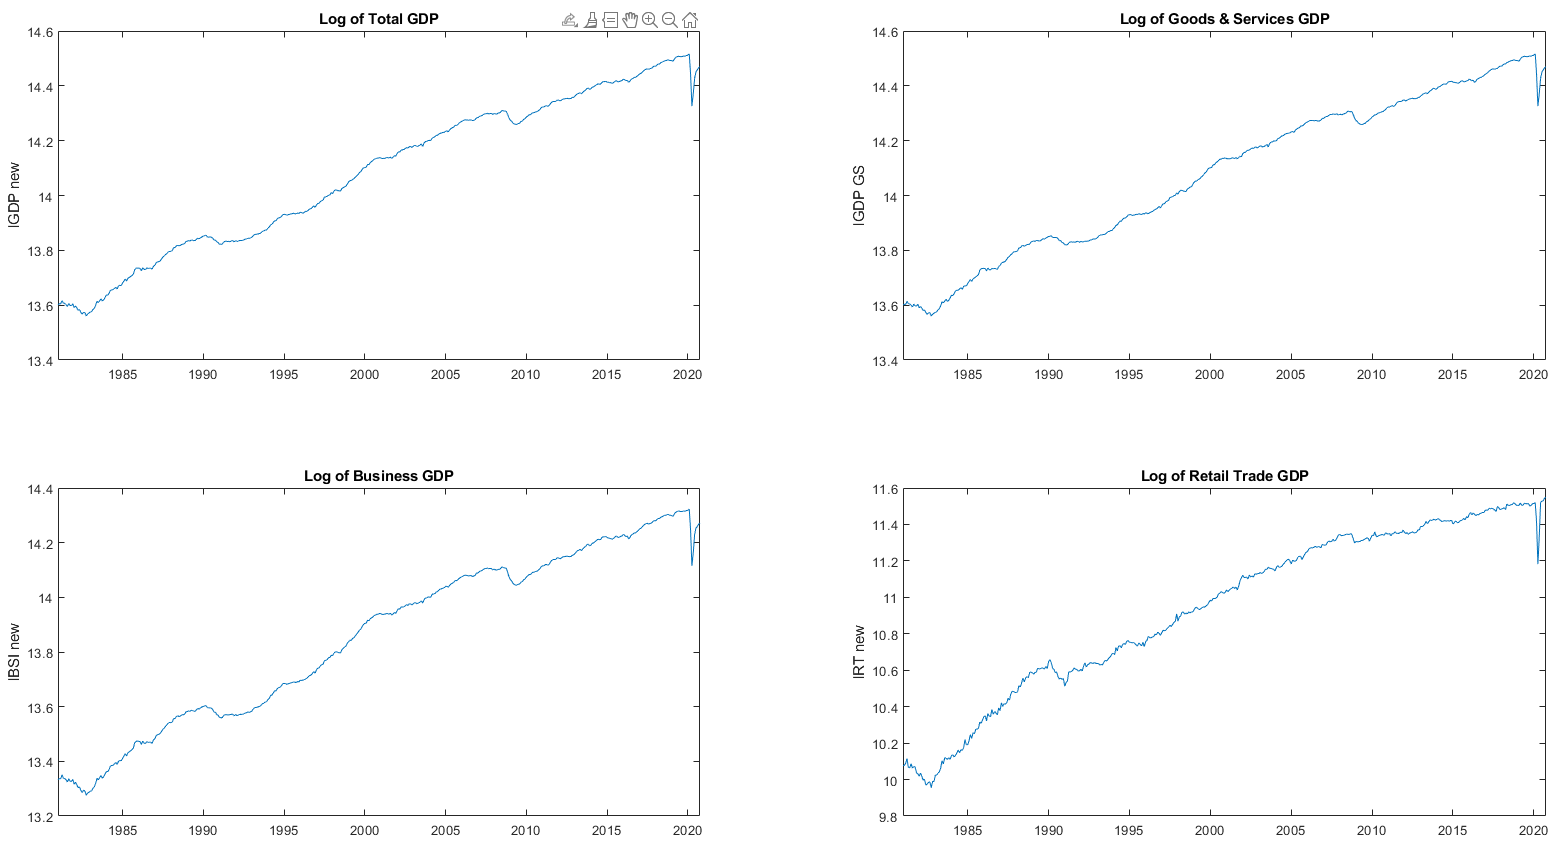

## Caculating the annualized growth rate of the level values (not log) of the four time series

% Create a for loop to calculate the annualized growth rate of each
% variable
idx = find(data.Date=='1982-01-01'); % Use semicolon ;  to suppress output (ie. run calculations quietly)
row = 1;
for t = idx:479
    gGDP_new(row,1) = ((GDP_new(t)/GDP_new(t-1))^12-1)*100;
    gGDP_GS(row,1) = ((GDP_GS(t)/GDP_GS(t-1))^12-1)*100;
    gBSI_new(row,1) = ((BSI_new(t)/BSI_new(t-1))^12-1)*100;
    gRT_new(row,1) = ((RT_new(t)/RT_new(t-1))^12-1)*100;
    row = row + 1;
end

% Display first 5 rows of our variables
table_g = [gGDP_new(1:5) gGDP_GS(1:5) gBSI_new(1:5) gRT_new(1:5)];
TABLE_g = array2table(table_g,'VariableNames',{'gGDP_new','gGDP_GS','gBSI_new','gRT_new'})

TABLE_g = 5×4 table
    gGDP_new    gGDP_GS    gBSI_new    gRT_new
    ________    _______    ________    _______

    -15.147     -15.138    -19.508     -14.135
     7.0031      7.0327     9.7736      21.888
    -7.4483     -7.4081    -9.7736     -17.958
    -10.453     -10.184    -13.111     -23.208
     3.4142      3.3519     4.0963      5.6886


The matrix below is a table of the first 5 rows (months) for our annualized growth rates for each of the respective variables: 

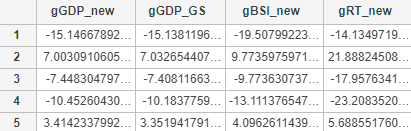

## Calculating the year-over-year growth rate

% Create a for loop to calculate the annualized growth rate of each
% variable
idx = find(data.Date=='1982-01-01'); % Use semicolon ;  to suppress output (ie. run calculations quietly) 
row = 1;
for t = idx:479
    gyGDP_new(row,1) = (GDP_new(t)/GDP_new(t-12)-1)*100;
    gyGDP_GS(row,1) = (GDP_GS(t)/GDP_GS(t-12)-1)*100;
    gyBSI_new(row,1) = (BSI_new(t)/BSI_new(t-12)-1)*100;
    gyRT_new(row,1) = (RT_new(t)/RT_new(t-12)-1)*100;
    row = row + 1;
end

% Display first 5 rows of our variables
table_gy = [gyGDP_new(1:5) gyGDP_GS(1:5) gyBSI_new(1:5) gyRT_new(1:5)];
TABLE_gy = array2table(table_gy,'VariableNames',{'gyGDP_new','gyGDP_GS','gyBSI_new','gyRT_new'})

TABLE_gy = 5×4 table
    gyGDP_new    gyGDP_GS    gyBSI_new    gyRT_new
    _________    ________    _________    ________

      -1.093       -1.057     -1.7284     -5.6699 
    -0.83575     -0.79475     -1.3039     -4.1566 
     -1.3925      -1.3531     -2.0564     -6.7936 
     -3.4383      -3.3621      -4.617     -11.152 
     -2.3545      -2.2891     -3.1446     -6.3949 


The matrix below is a table of the first 5 rows (months) for our year-over-year growth rates for each of the respective variables: 

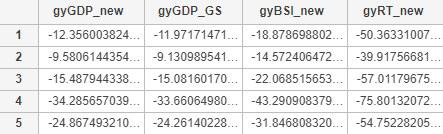

## Distinction between annual percent change, annualized growth rate, and year-over-year growth rates.

Annual percent change (ex: (GDP_2020/GDP_2019 - 1)*100) compares the GDP from one year to the next.  When the annual percent change is positive the economy is growing, conversely, when the annual percent change is negative, the economy is declining. 

We can use the year-over-year (Y/Y) growth rate to compare how a variables has changed from one period to the same period in the previous year. In other words, this is a cross-comparison of monthly data with that of the previous year (ex., January 2020 vs January 2019). While it compares the figures of two years it is not an annualized measure, and does not need to be annualized because it is an annual difference. 

The annualized (monthly) growth rate calculates how much growth rates would have changed over a year's time, if it had grown at the same rate. This measure takes into account a compounding effect (ex: GDP_2020/GDP_2019^t), and can be thought of as adjusting the growth rate to reflect the rate of growth over a year's time had it continued to grow at the given rate of the period. 

For example, if we wanted to know how much a variable changed over a year if it had the same growth rate and we had monthly or quarterly data, we would use the annualized growth rate.

## Subplots for annualized growth rate and y/y growth rate of real variables.

% First need to index the dates
idx = find(data.Date=='1982-01-01')

idx = 13

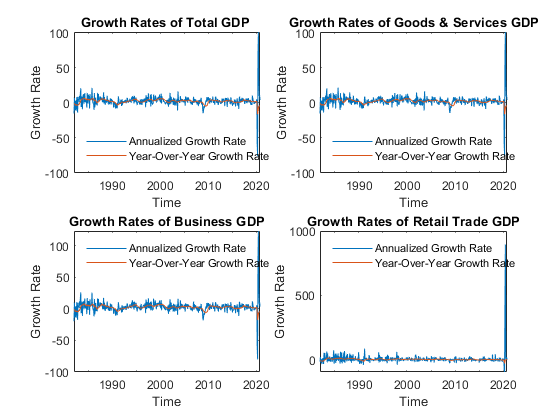


% Create subplots 
figure(2) % Figure 2
subplot(2,2,1)
plot(data.Date(idx:479),gGDP_new);
hold on
    plot(data.Date(idx:479),gyGDP_new);
title("Growth Rates of Total GDP ");
xlabel("Time");
ylabel("Growth Rate");
legend("Annualized Growth Rate","Year-Over-Year Growth Rate",'Location','SouthWest');
legend boxoff;

subplot(2,2,2)
plot(data.Date(idx:479),gGDP_GS);
hold on
    plot(data.Date(idx:479),gyGDP_GS);
title("Growth Rates of Goods & Services GDP");
xlabel("Time");
ylabel("Growth Rate");
legend("Annualized Growth Rate","Year-Over-Year Growth Rate",'Location','SouthWest');
legend boxoff;

subplot(2,2,3)
plot(data.Date(idx:479),gBSI_new);
hold on
    plot(data.Date(idx:479),gyBSI_new);
title("Growth Rates of Business GDP");
xlabel("Time");
ylabel("Growth Rate");
legend("Annualized Growth Rate","Year-Over-Year Growth Rate",'Location','NorthWest');
legend boxoff;

subplot(2,2,4)
plot(data.Date(idx:479),gRT_new);
hold on
    plot(data.Date(idx:479),gyRT_new);
title("Growth Rates of Retail Trade GDP");
xlabel("Time");
ylabel("Growth Rate");
legend("Annualized Growth Rate","Year-Over-Year Growth Rate",'Location','NorthWest');
legend boxoff;

We can see in all four segments, the rate of change in GDP declined drastically in about April of 2020, and shot up drastically after many businesses in the economy reopened. 

## Detrending each of the 4 time series using HP filter

% HP filter doesn't work with NaN (missing values)
% Change NaN values to 0 may get us the result we want
    % lGDP_new(479) = 0
    % lGDP_GS(479) = 0
    % lBSI_new(479) = 0
    % lRT_new(479) = 0     % Not sure if this is correct

% Apply HP filter & calculate the cycle
tlGDP_new = hpfilter(lGDP_new(1:478),129600)   % Monthly lambda = 129,600

tlGDP_new =    13.5654
   13.5673
   13.5692
   13.5711
   13.5730
   13.5749
   13.5767
   13.5786
   13.5805
   13.5825


clGDP_new = lGDP_new(1:478) - tlGDP_new        % Extract cycle 

clGDP_new =     0.0368
    0.0380
    0.0353
    0.0452
    0.0349
    0.0316
    0.0260
    0.0160
    0.0254
    0.0164



tlGDP_GS = hpfilter(lGDP_GS(1:478),129600) 

tlGDP_GS =    13.5639
   13.5658
   13.5677
   13.5696
   13.5715
   13.5734
   13.5753
   13.5772
   13.5791
   13.5811


clGDP_GS = lGDP_GS(1:478) - tlGDP_GS 

clGDP_GS =     0.0365
    0.0377
    0.0350
    0.0447
    0.0345
    0.0311
    0.0254
    0.0159
    0.0249
    0.0161



tlBSI_new = hpfilter(lBSI_new(1:478),129600) 

tlBSI_new =    13.2894
   13.2913
   13.2932
   13.2951
   13.2971
   13.2990
   13.3009
   13.3029
   13.3048
   13.3068


clBSI_new = lBSI_new(1:478) - tlBSI_new

clBSI_new =     0.0439
    0.0455
    0.0426
    0.0555
    0.0416
    0.0374
    0.0321
    0.0213
    0.0315
    0.0204



tlRT_new = hpfilter(lRT_new(1:478),129600) 

tlRT_new =     9.9822
    9.9860
    9.9898
    9.9936
    9.9973
   10.0011
   10.0049
   10.0088
   10.0126
   10.0165


clRT_new = lRT_new(1:478) - tlRT_new

clRT_new =     0.0949
    0.0917
    0.0994
    0.1214
    0.0701
    0.0632
    0.0824
    0.0544
    0.0585
    0.0534



% This question did not ask for a plot


## Creating output gap variable

% Create output gap, YGAP (deviations of actual from trend)
YGAP = clGDP_new * 100

YGAP =     3.6837
    3.7998
    3.5296
    4.5177
    3.4928
    3.1556
    2.6044
    1.6036
    2.5365
    1.6385


## Plotting output gap, annualized and Y/Y growth rates on one graph

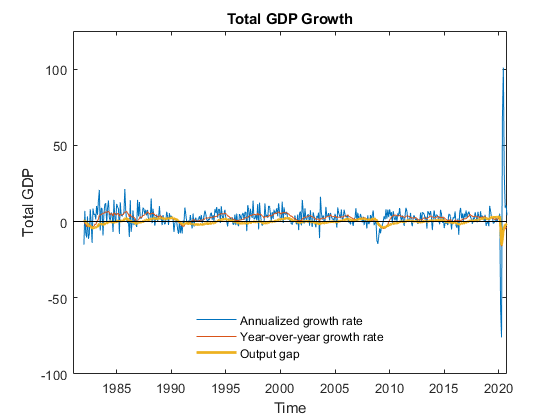

% % Index dates
idx2 = find(data.Date=='1982-01-01');
 
% Total GDP
figure(3) % Figure 3
plot(data.Date(idx2:478),gGDP_new(1:466));
hold on
    plot(data.Date(idx2:478),gyGDP_new(1:466));
    plot(data.Date(idx2:478),YGAP(idx:478),'LineWidth',2);
    plot(data.Date(1:478),zeros(length(data.Date(1:478)),1),'k-');
xlabel("Time");
ylabel("Total GDP");
ylim([-100 125]);
title("Total GDP Growth")
legend("Annualized growth rate", "Year-over-year growth rate", "Output gap", "Location","South");
legend boxoff;

Graph output from commands above:

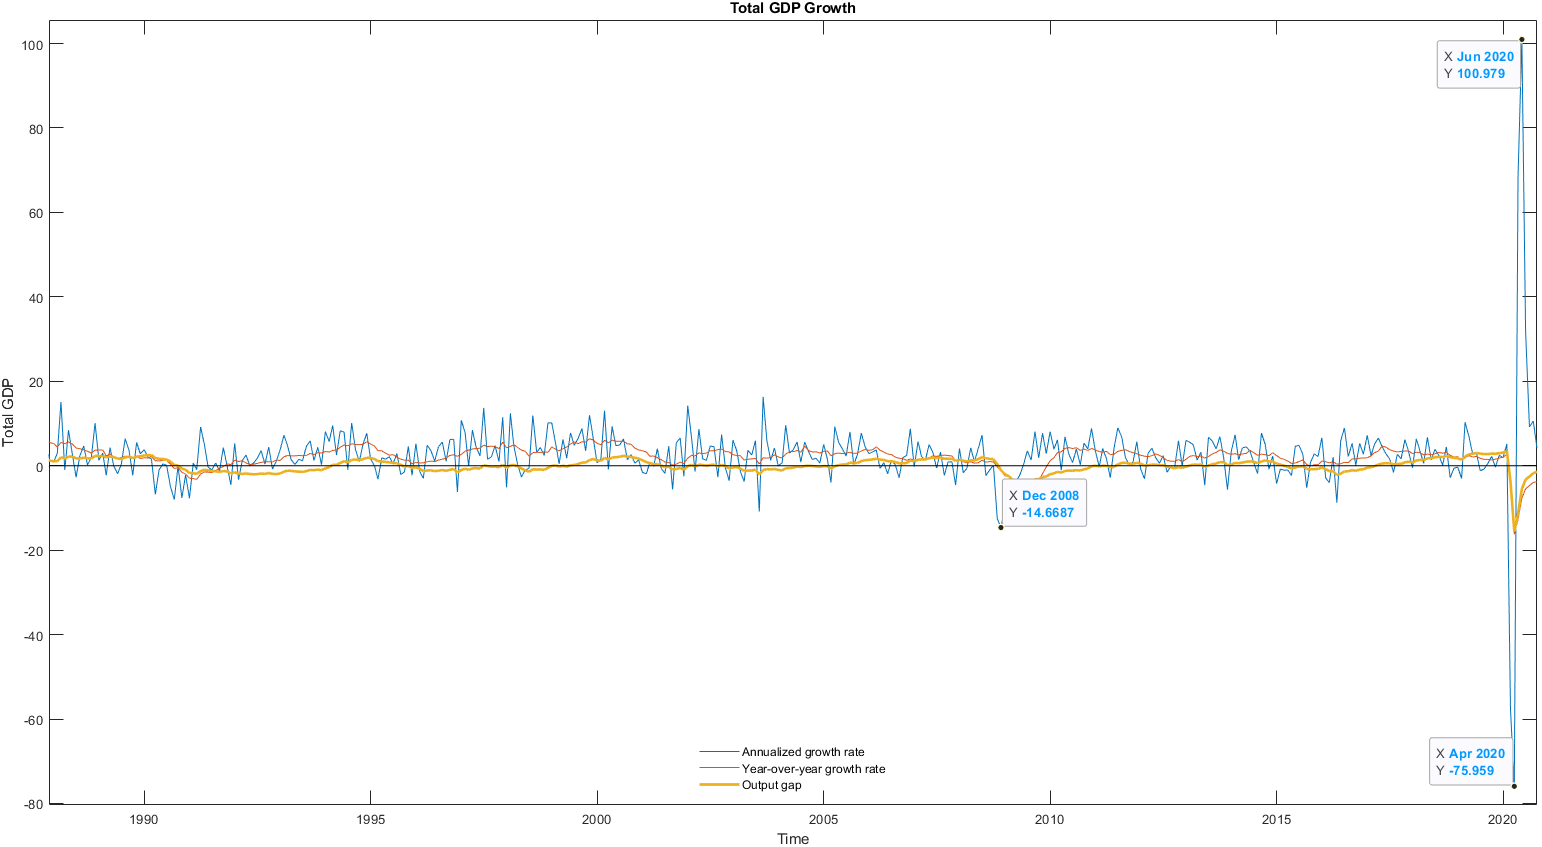

Recall that the output gap = actual real GDP - real GDP trend, which is pretty much the real GDP cycle. 

The annualized growth rate shows the largest fluctuations, while the year-over-year growth rate follows the real GDP cycle. We can see that the rate of change of real GDP declined drastically in April 2020 (possibly due to lockdowns and uncertainties for both consumers and producers), and shot up drastically by June 2020 when many businesses in economy reopened. 

## Graphing the real retail trade GDP cycle using log levels

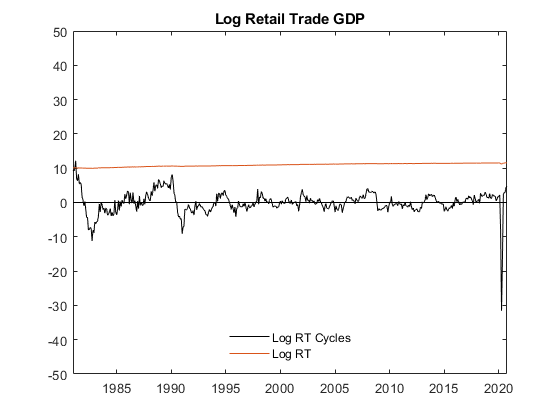

% Index dates
idx3 = find(data.Date=='1982-01-01');

% Business GDP
figure(4) % Figure 4
plot(data.Date(1:478),clRT_new(1:478)*100,'k-');
hold on
    plot(data.Date(1:478),lRT_new(1:478));
    plot(data.Date(1:478),zeros(length(data.Date(1:478)),1),'k-');
ylim([-50 50]);
title("Log Retail Trade GDP")
legend("Log RT Cycles", "Log RT", "Location","South");
legend boxoff;

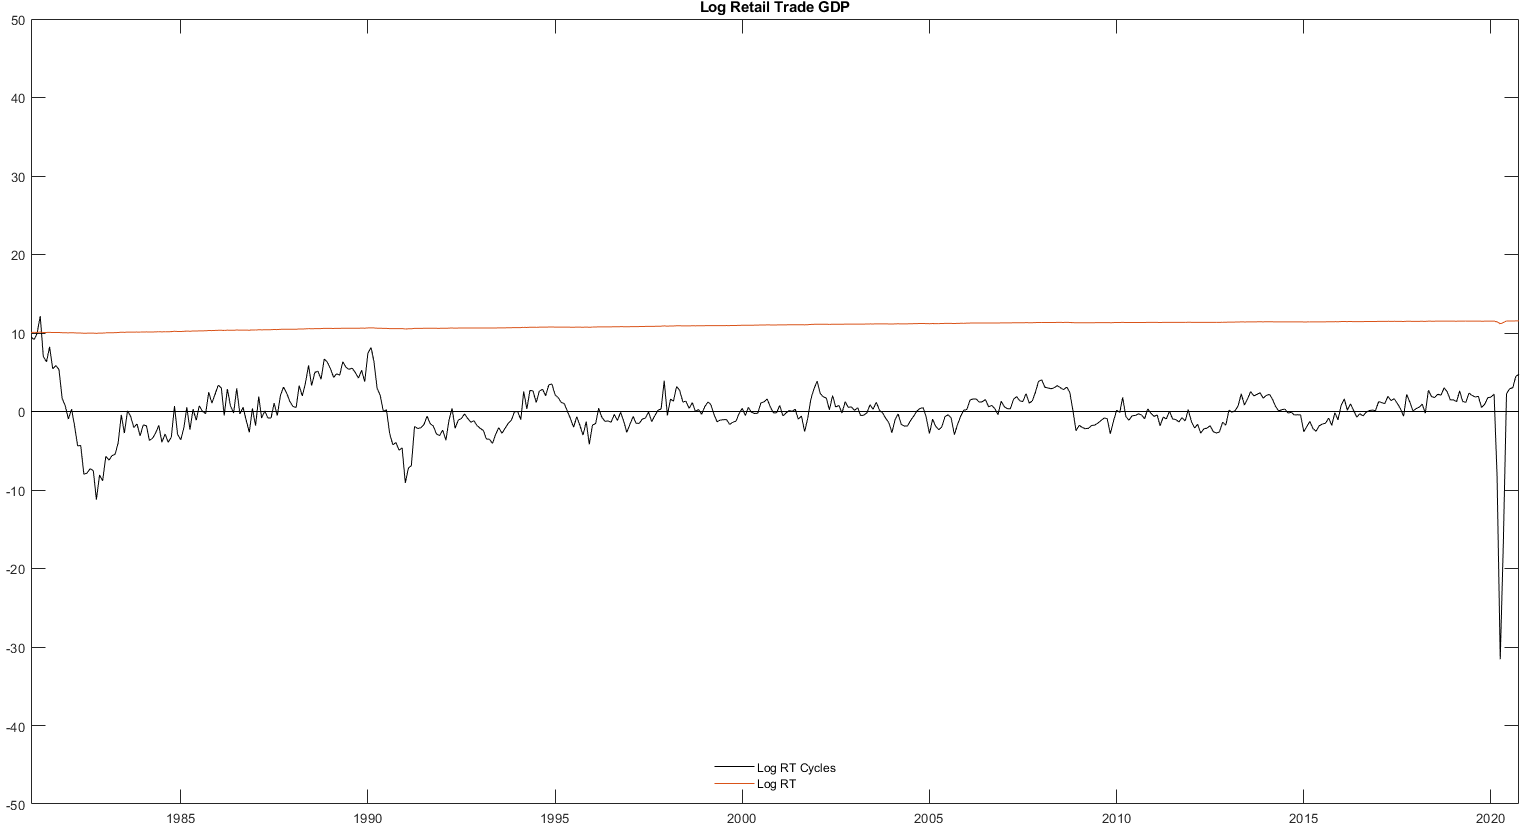

After detrending the data with the HP filter, we extract the real retail trade GDP cycle about the zero line. Here we can see that the fall in retail trade GDP after March 2020 was by far the largest since 1982 (deviation from trend was greater than 40%), making the 2008-2009 financial crisis look insignificant by comparison. The real retail trade GDP *trend*, however, shows a much smoother slightly upward trend. This graph emphasizes the serverity of the COVID-19 shock.